b = imread("bild07 (1).png");

b = 480×640 uint8 matrix
   88   87   86   85   84   84   85   85   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   85   86   88   90   91   90   88
   88   87   86   85   84   84   85   85   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   85   86   88   90   91   90   88
   88   87   86   85   84   84   85   85   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   85   86   88   90   91   90   88
   88   87   86   85   84   84   85   85   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   84   85  

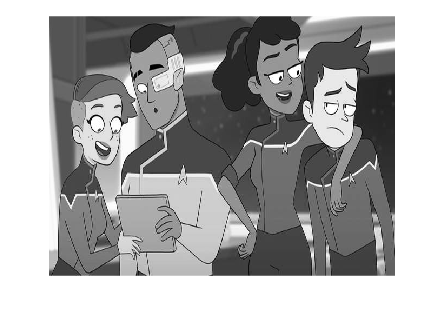

imshow(b);

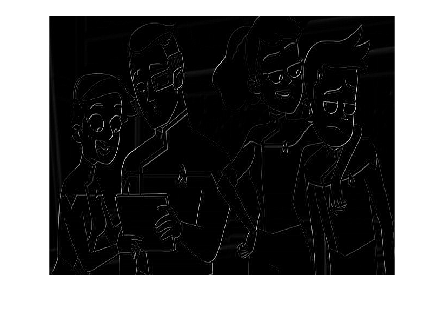

ergebnis1 = uebung3(b);
imshow(ergebnis1);

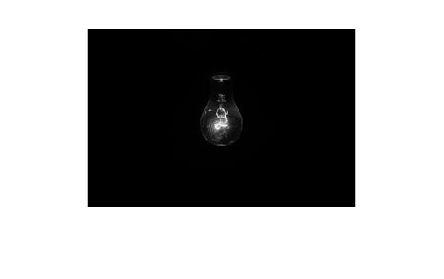


bild = imread('images.jpg');
bild = rgb2gray(bild);
imshow(bild);

bild2 = adjustBrightnessWithGauss(bild, 22);

Error using eye
Requested 50325x50325 (18.9GB) array exceeds maximum array size preference (15.7GB). This might cause MATLAB to become unresponsive.

Error in reverse>adjustBrightnessWithGauss (line 26)
    A = eye(length(imageVector));

Related documentation

imshow(bild2);

function adjustedImage = adjustBrightnessWithGauss(originalImage, brightnessIncrease)
    % Konvertieren Sie das Bild in Graustufen, falls es farbig ist
    if size(originalImage, 3) == 3
        grayImage = rgb2gray(originalImage);
    else
        grayImage = originalImage;
    end

    % Bildgröße bestimmen
    [rows, cols] = size(grayImage);

    % Bilddaten in einen Vektor umwandeln
    imageVector = double(grayImage(:));

    % Koeffizientenmatrix erstellen (Identitätsmatrix)
    A = eye(length(imageVector));
    
    % Konstantenvektor (Erhöhung der Helligkeit um brightnessIncrease)
    b = brightnessIncrease * ones(length(imageVector), 1);
    
    % Augmentierte Matrix erstellen
    Ab = [A b];
    
    % Anzahl der Zeilen
    n = size(Ab, 1);
    
    % Gauss-Elimination
    for i = 1:n
        % Pivotisierung (falls nötig)
        [~, maxIndex] = max(abs(Ab(i:n, i)));
        maxIndex = maxIndex + i - 1;
        if maxIndex ~= i
            Ab([i, maxIndex], :) = Ab([maxIndex, i], :);
        end
        
        % Eliminierung
        for j = i+1:n
            factor = Ab(j, i) / Ab(i, i);
            Ab(j, i:end) = Ab(j, i:end) - factor * Ab(i, i:end);
        end
    end
    
    % Rückwärtseinsetzen
    x = zeros(n, 1);
    for i = n:-1:1
        x(i) = (Ab(i, end) - Ab(i, 1:end-1) * x) / Ab(i, i);
    end
    
    % Bilddaten zurück in die ursprüngliche Form bringen
    brightenedImage = reshape(x, [rows, cols]);
    
    % Sicherstellen, dass die Pixelwerte im gültigen Bereich liegen
    brightenedImage(brightenedImage > 255) = 255;
    brightenedImage(brightenedImage < 0) = 0;
    
    % Konvertierung zurück zu uint8
    brightenedImage = uint8(brightenedImage);
    
    % Rückgabe des angepassten Bildes
    adjustedImage = brightenedImage;
    
    % Ergebnisbild anzeigen
    figure, imshow(adjustedImage), title('Bild mit erhöhter Helligkeit');
end



function ergebnis = uebung3(matrix)

    [zeilen,spalten] = size(matrix);
    
    ergebnis = matrix(1:zeilen-1,1:spalten-1);
    
    for z = 1:zeilen-1
        for s = 1:spalten-1
           differenz = matrix(z,s) - matrix(z+1,s+1);
           ergebnis(z,s) = abs(differenz);
        end
    end

end

function ergebnis = uebung3sss(bildmatrix, parameter2)
    [zeilen,spalten,~] = size(bildmatrix);
    
    ergebnis = bildmatrix(1:zeilen-1,1:spalten-1);
    
    for z = 1:zeilen-1
        for s = 1:spalten-1
           differenz = bildmatrix(z,s) - bildmatrix(z+1,s+1);
           ergebnis(z,s) = differenz;
        end
    end
end


function ergebnis = uebung3ss(bildMatrix, parameter2)

    % Eine Skalierungsoperation auf die Bildmatrix anwenden
    % Es wird angenommen, dass parameter2 ein Skalar ist
    ergebnis = uint8(double(bildMatrix) * parameter2);

    % Sicherstellen, dass das Ergebnis innerhalb des uint8-Bereichs [0, 255] liegt
    ergebnis(ergebnis > 255) = 255;
    ergebnis(ergebnis < 0) = 0;
end


function ergebnis = uebung3V1(bildmatrix, parameter2)
    % Bildgröße bestimmen
    [rows, cols] = size(bildmatrix);
    
    % Ausgabe initialisieren
    ergebnis = uint8(zeros(rows, cols));
    
    % Beispielhafte Transformation: Pixelwerte invertieren
    for i = 1:rows
        for j = 1:cols
            ergebnis(i, j) = 255 - bildmatrix(i, j);
        end
    end
end
